### (*Prev*.) Get preprocessed EEG data from EEGLAB

% eeglab;
% eeg = EEG.data;
% type = {EEG.event.type};
% latn = [EEG.event.latency];
% fs = EEG.srate;

# **ERP Analysis**

clc; close all; 

## Load dataset

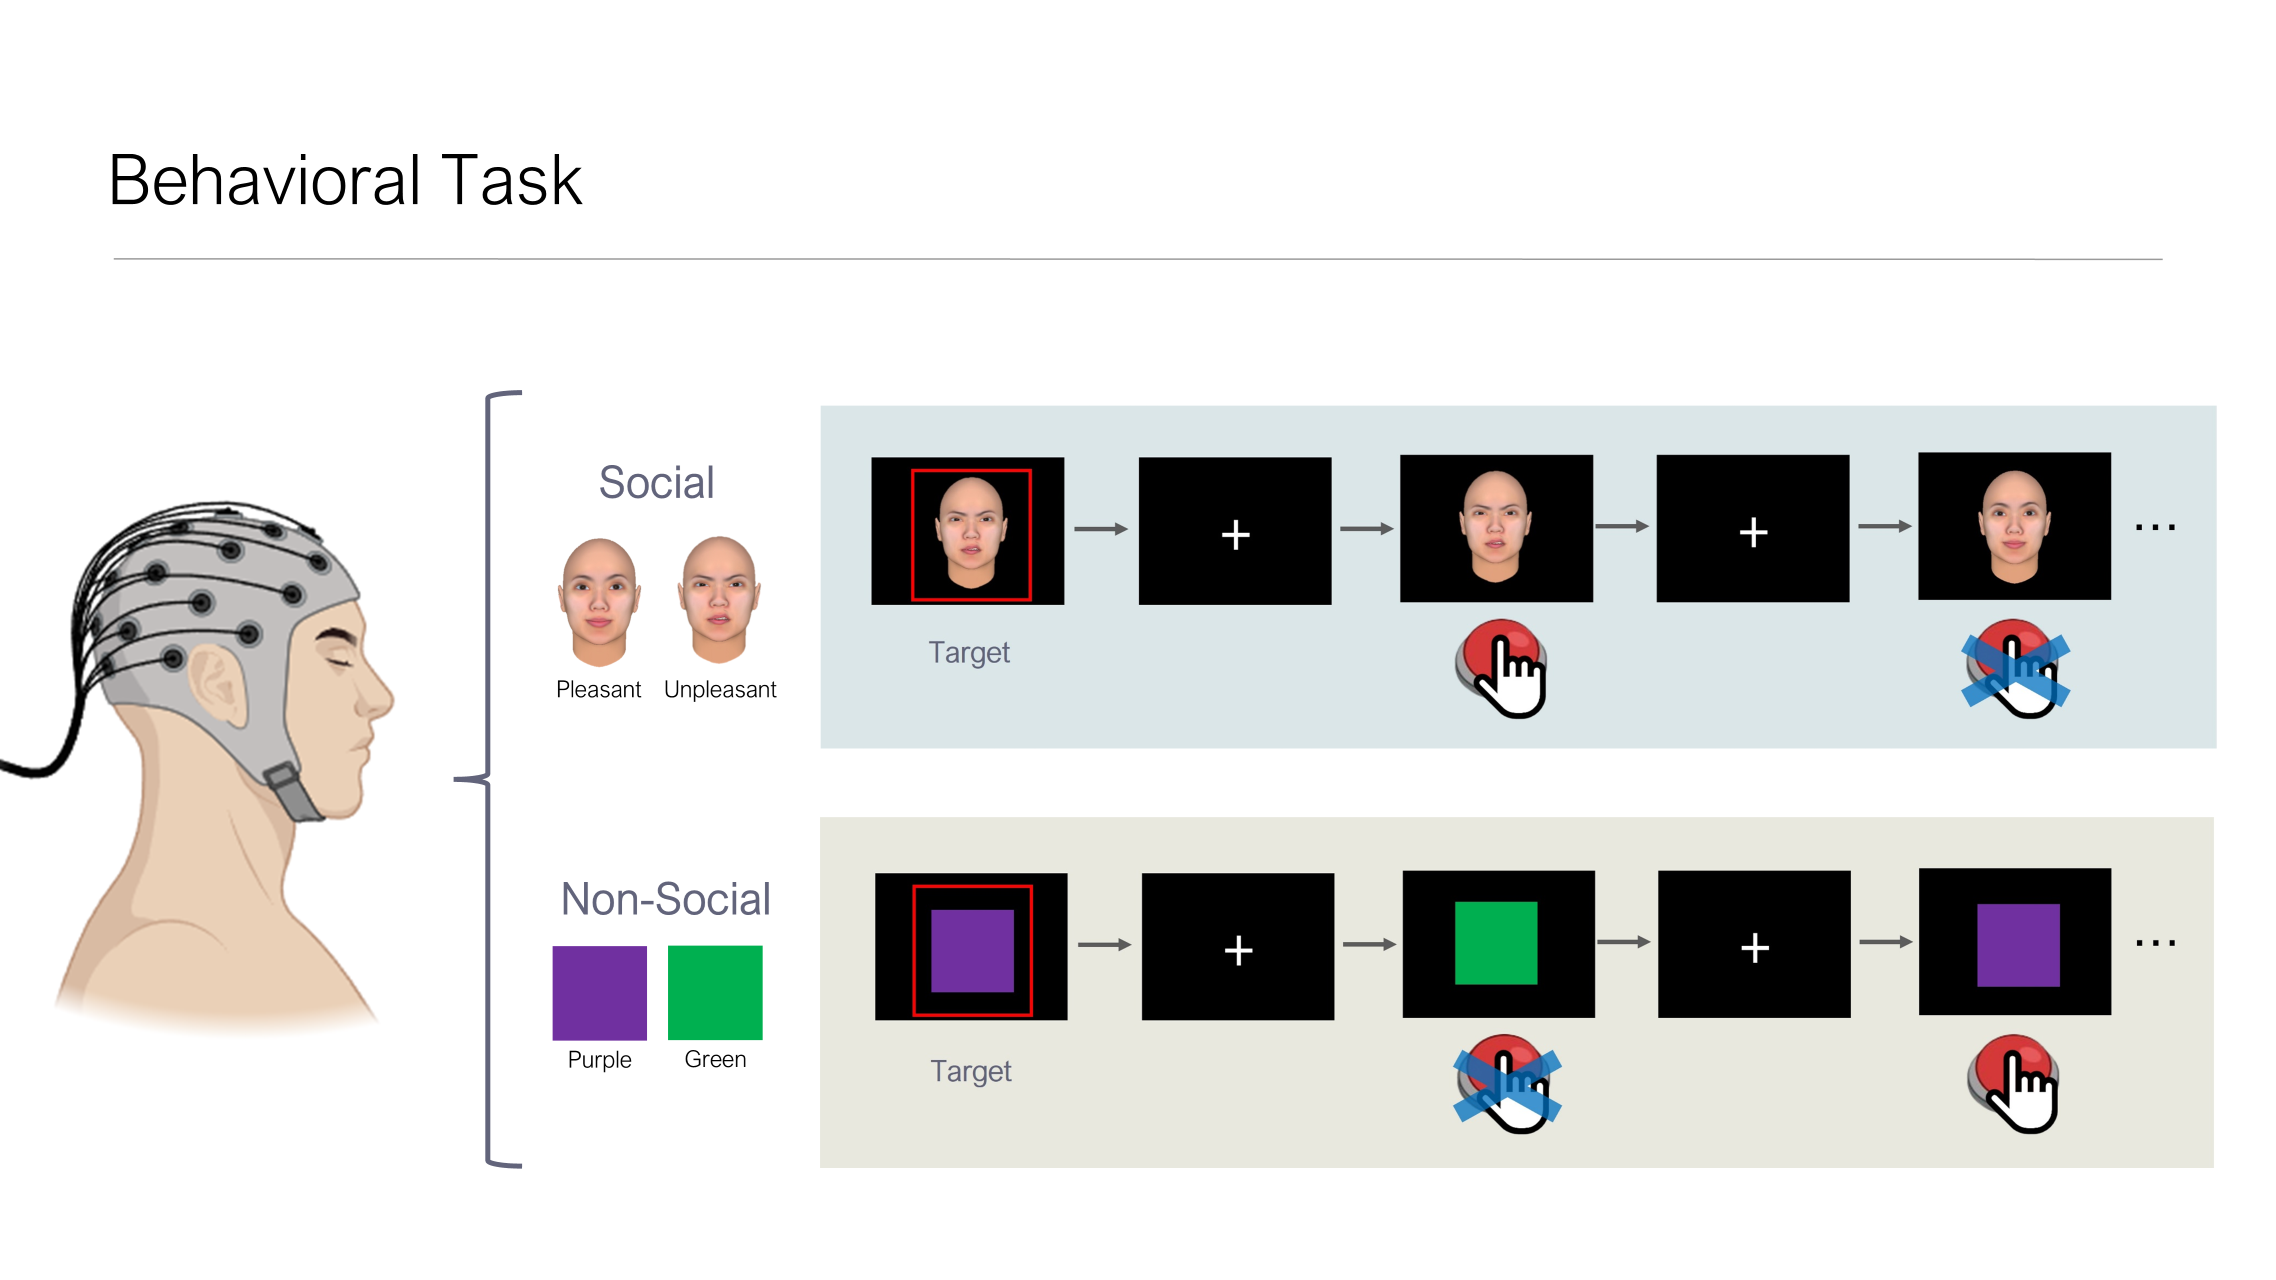

% preprocessing 
% 1) 0.5 - 40 Hz Filtering
% 2) Removing artifact (ASR) 
% 3) Smoothing (12Hz Low-pass filtering, 'optional')
data = importdata('dataSamples_EEG.mat')

data = 다음 필드를 포함한 1×10 struct 배열:
    eeg
    event
    fs
    chanName
    IsPatients


nsubj = length(data)

nsubj = 10

**Get sample subject's EEG data**

% get any sample subject
sample_idx = 6;

eeg = data(sample_idx).eeg;
fs = data(sample_idx).fs;

nch = size(eeg, 1)

nch = 31

chanName = data.chanName

chanName = 1×31 cell 배열
    {'Fp1'}    {'Fpz'}    {'Fp2'}    {'F7'}    {'F3'}    {'Fz'}    {'F4'}    {'F8'}    {'FC9'}    {'FC5'}    {'FC1'}    {'FC2'}    {'FC6'}    {'FC10'}    {'T7'}    {'C3'}    {'Cz'}    {'C4'}    {'T8'}    {'CP5'}    {'CP1'}    {'CP2'}    {'CP6'}    {'P7'}    {'P3'}    {'Pz'}    {'P4'}    {'P8'}    {'O1'}    {'Oz'}    {'O2'}


**Get event onset information **

The ratio of the numbr of  Go and No-Go trial is 30 : 70 for each task (social & non-social).

- S  10 = Social/Go (SG)

- S  11 = Social/NoGo (SN)

- S  20 = Nonsocial/Go (NG)

- S  21 = Nonsocial/NoGo (NN)

event_idx = ismember( data(sample_idx).event.type, {'S  10', 'S  11', 'S  20', 'S  21'} );
event_name = data(sample_idx).event.type(event_idx);
event_onset = data(sample_idx).event.latency(event_idx);

ntrial = length(event_name)

ntrial = 200

conditional indexing

SG_trial_idx = strcmp(event_name, 'S  10');
length( find(SG_trial_idx) )

ans = 30

SN_trial_idx = strcmp(event_name, 'S  11');
length( find(SN_trial_idx) )

ans = 70

NG_trial_idx = strcmp(event_name, 'S  20');
length( find(NG_trial_idx) )

ans = 30

NN_trial_idx = strcmp(event_name, 'S  21');
length( find(NN_trial_idx) )

ans = 70

## Epoching

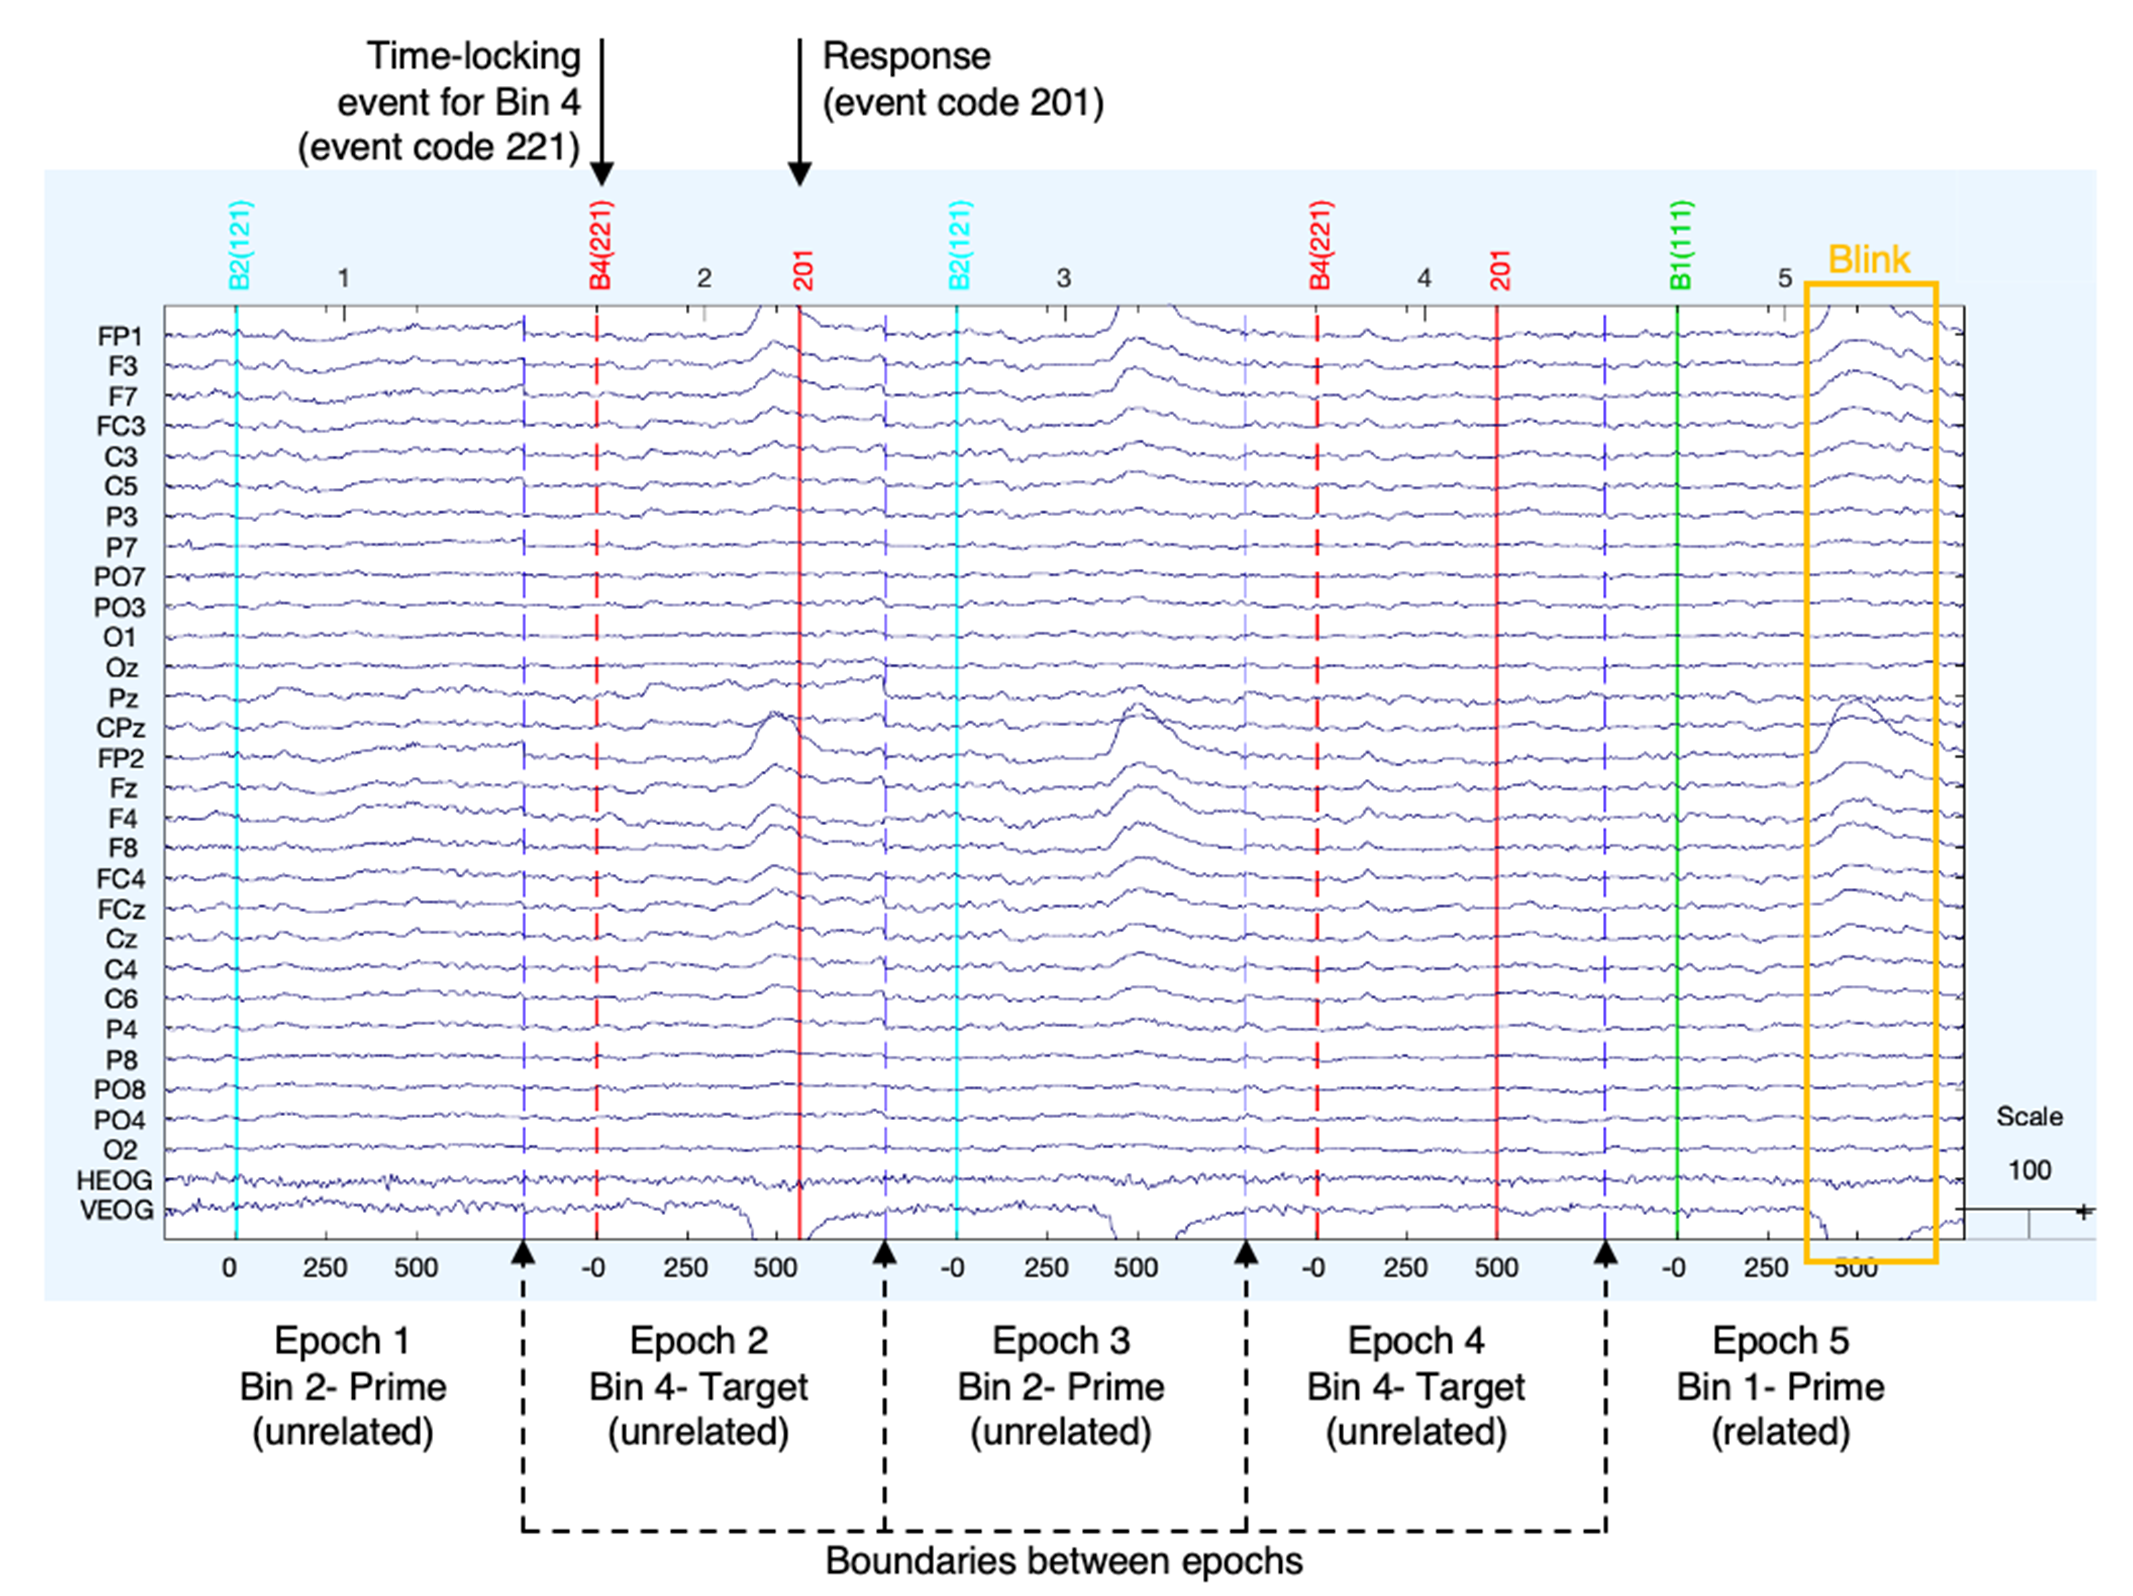

#### Step1. Define window (Bin) length

epoch_win = [-.2 1]; % [start end] (sec).
time = epoch_win(1):1/fs:epoch_win(2);

#### Step2. Epoching for defined window length

#### `!!!Fill the blank!!!`

EP = []; 
for itrial = 1: ntrial
    itrial_event_onset = event_onset(itrial);
    itrial_winpnt = itrial_event_onset + epoch_win*fs;

    EP(:,:,itrial) = eeg(:, itrial_winpnt(1):itrial_winpnt(2));
end

#### Step3. Baseline Correction

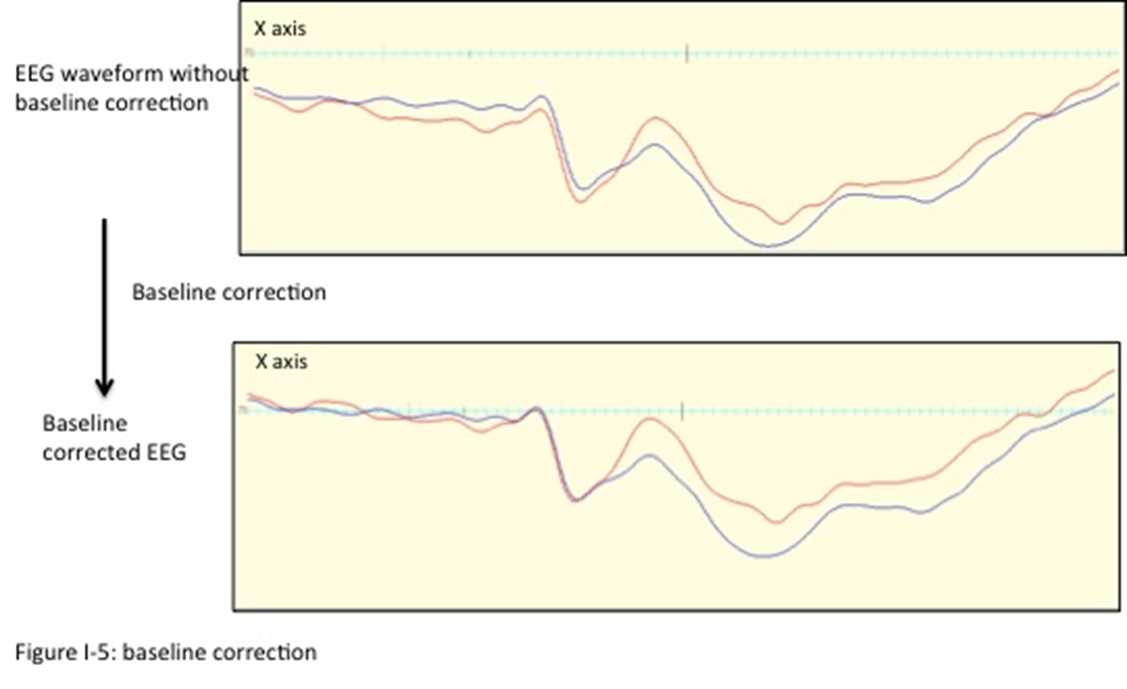

Define prestimulus(baseline) window 

base_win = [-0.2 0]; % sec.
baseidx = find( time >= base_win(1) & time <= base_win(2) );

prestim_EP = EP(:, baseidx, :);

#### `!!!Fill the blank!!!`

basecorr_EP = EP - mean( prestim_EP, 2 );

#### Step4. Trial Average according to each condition

SG_EP = EP(:,:,SG_trial_idx);
SN_EP = EP(:,:,SN_trial_idx);
NG_EP = EP(:,:,NG_trial_idx);
NN_EP = EP(:,:,NN_trial_idx);

avg_SG_EP = mean(SG_EP,3);
avg_SN_EP = mean(SN_EP,3);
avg_NG_EP = mean(NG_EP,3);
avg_NN_EP = mean(NN_EP,3);

Plotting conditional ERPs

ch_idx = [6 17 26 30]; % Fz, Cz, Pz, Oz (midline)

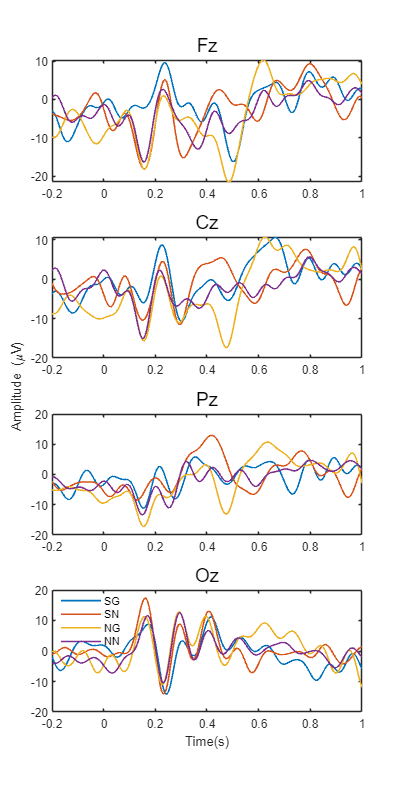

figure('Position', [400 40 400 800]);
tiledlayout(4,1);
for ich = ch_idx
    nexttile();

    plt(1) = plot(time, avg_SG_EP(ich,:),'LineWidth',1.2); hold on;
    plt(2) = plot(time, avg_SN_EP(ich,:),'LineWidth',1.2); 
    plt(3) = plot(time, avg_NG_EP(ich,:),'LineWidth',1.2); 
    plt(4) = plot(time, avg_NN_EP(ich,:),'LineWidth',1.2); 

    title(chanName{ich}, 'FontSize',14); 
end

% legend options
legend(plt, {'SG' 'SN' 'NG' 'NN'}, 'Location','best','box','off');

% figure options
ax = axes('Visible','off');
ax.XLabel.Visible = 'on';
ax.YLabel.Visible = 'on';
xlabel('Time(s)');
ylabel('Amplitude (\muV)');

## Classifying ERP components

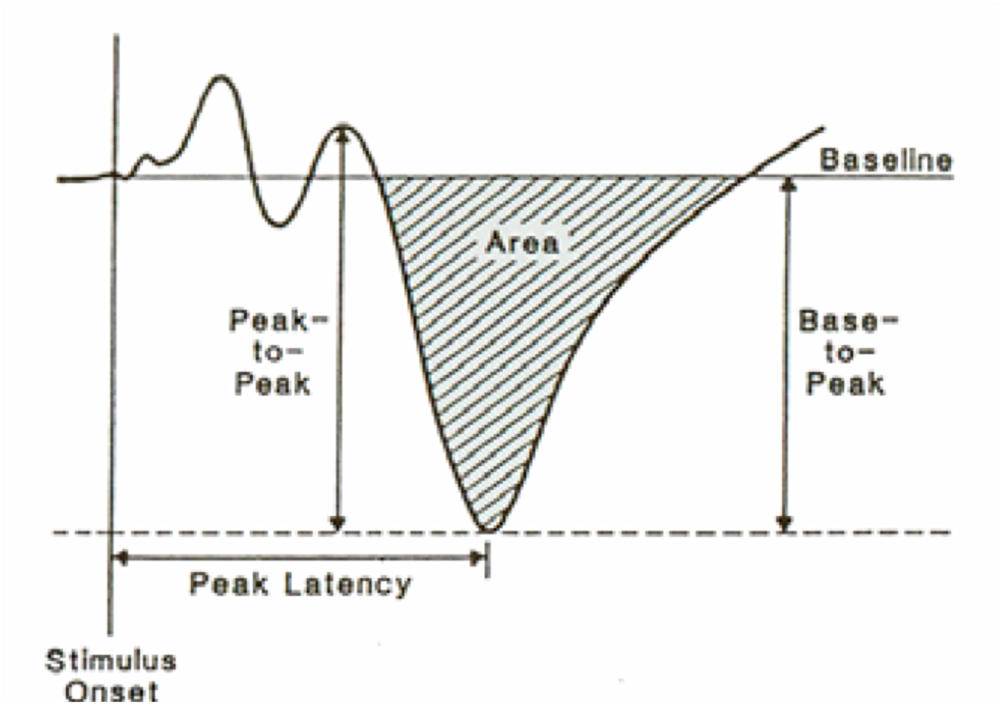

•Polarity (positive or negative)

•Latency

•**Area**

•Scalp locations

#### Area amplitude

area_win = [0.2 0.4]; % sec
timeidx = area_win(1) < time & area_win(2) >= time;

#### `!!!Fill the blank!!!`

about trapz function (doc trapz)

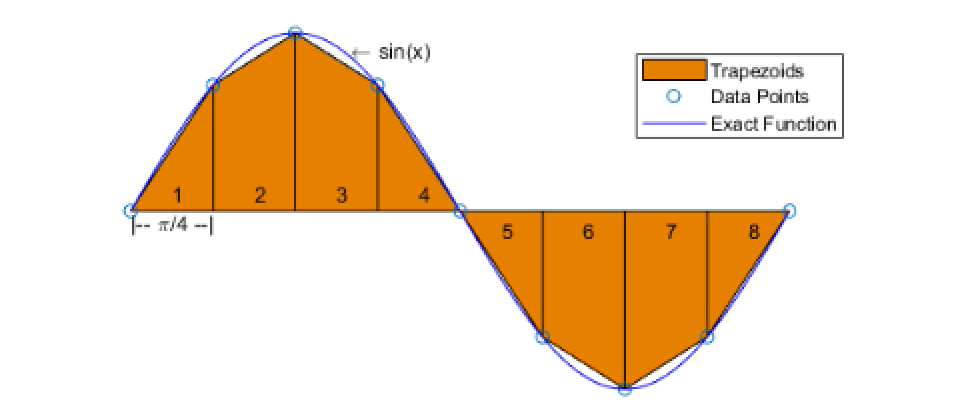

% x-axis : seconds
% y-axis : amplitude
% hint: please use 'timeidx'  and 'EP' variables.
% EP = ch*time*trials matrix
area_EP = trapz( 1./fs, EP(:, timeidx,:), 2 );

Trial averaged mean area amplitude

tr_avg_area = [];
tr_avg_area(:,1) = mean( area_EP(:,:,SG_trial_idx), 3); % SG
tr_avg_area(:,2) = mean( area_EP(:,:,SN_trial_idx), 3); % SN
tr_avg_area(:,3) = mean( area_EP(:,:,NG_trial_idx), 3); % NG
tr_avg_area(:,4) = mean( area_EP(:,:,NN_trial_idx), 3); % NN

plotting area amplitude for an example channel

ch_idx = 30; % Oz

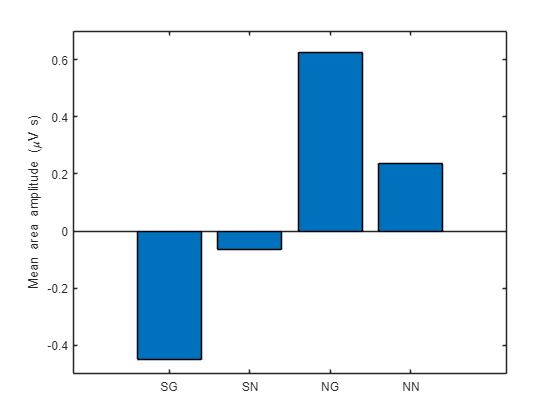

figure();
bar([1:4], tr_avg_area(ch_idx,:));

% figure options
xlim('padded'); ylim('padded');
set(gca,'XTick',[1:4], 'XTickLabels', {'SG' 'SN' 'NG' 'NN'});
ylabel('Mean area amplitude (\muV s)')

#### ERP Topography

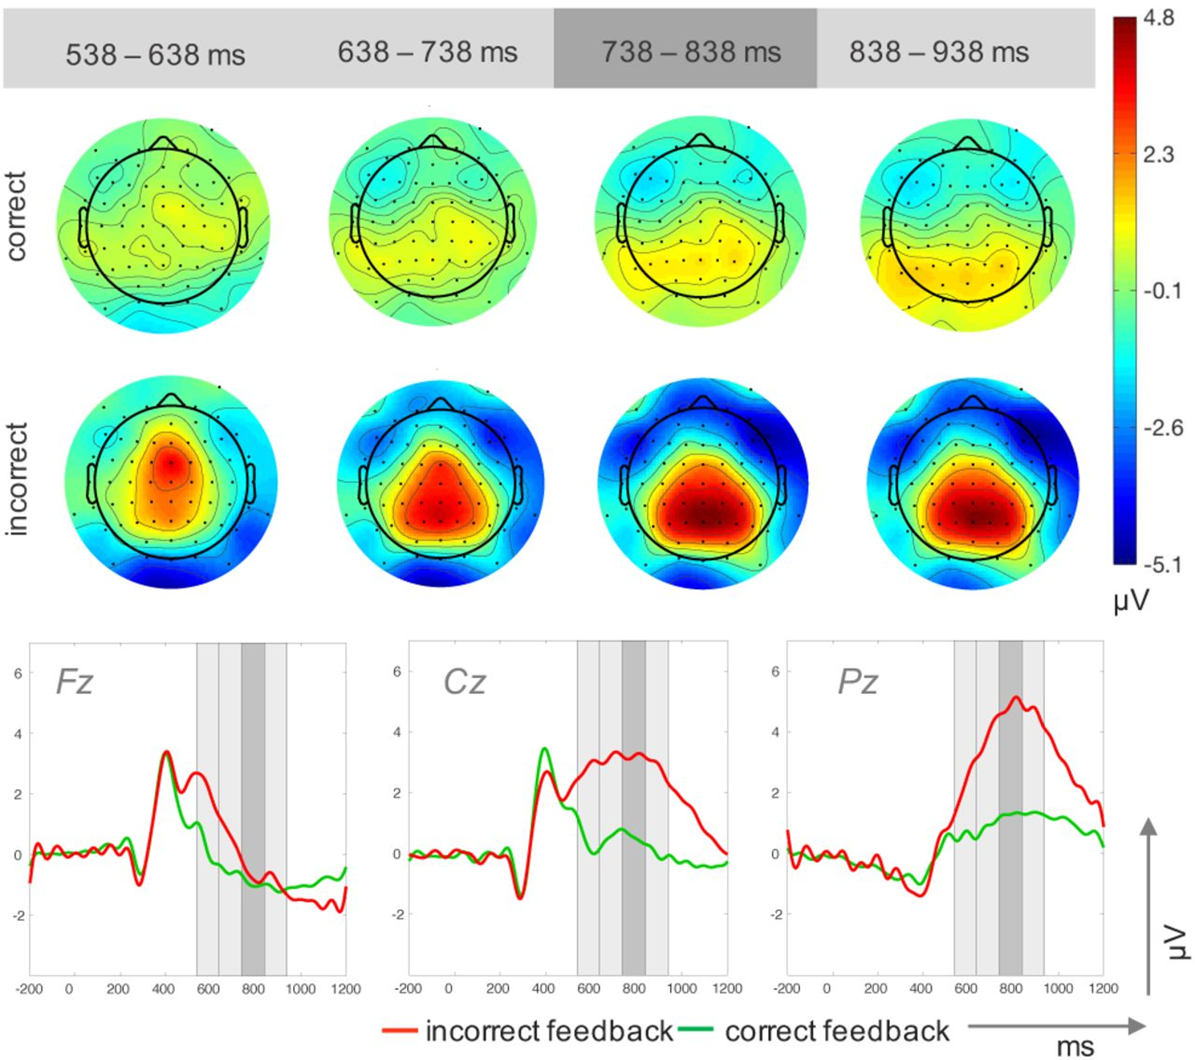

titlename = {'SG' 'SN' 'NG' 'NN'};
figure('Position',[680 640 1150 240]);
tiledlayout(1,4);
for i = 1: size(tr_avg_area,2)
    nexttile();

    topoplot( tr_avg_area(:,i), 'BP_channelLocs.locs', 'whitebk','on');
    caxis([-5 5])

    % figure options
    title(titlename{i});
end

readlocs(): 'loc' format assumed from file extension


readlocs(): 'loc' format assumed from file extension


readlocs(): 'loc' format assumed from file extension


readlocs(): 'loc' format assumed from file extension


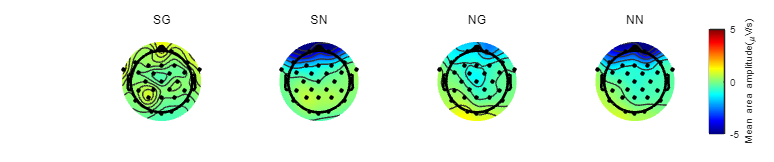

% colorbar option
cb = colorbar;
cb.Layout.Tile ='east';
set(get(cb,'Label'), 'String', 'Mean area amplitude(\muV/s)');